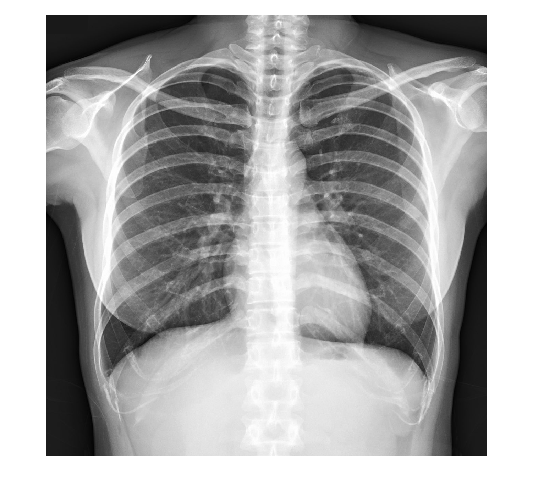

f=imread('radiograph1.jpg');
f=double(f(:,:,1));
figure(1);
imshow(f,[]);

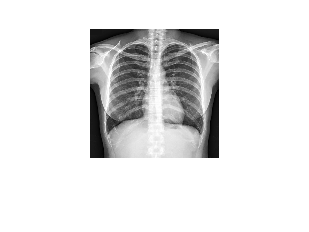

pet=imresize(f,0.1,'nearest');
figure (2);
imshow(pet,[])

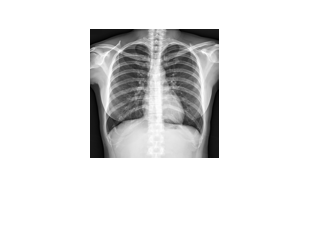

pet=imresize(f,0.1,'bicubic');
figure (3);
imshow(pet,[])

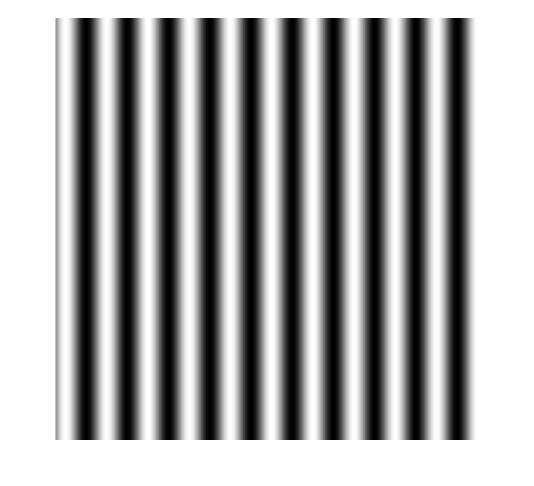

sine=zeros(1024);
k=0.01;
for(x=1:1024)
    for (y=1:1024)
        sine(y,x)=10+sin(x*k*(1+0.00*y)*2*pi);
    end
end
figure(1);
imshow(sine,[]);

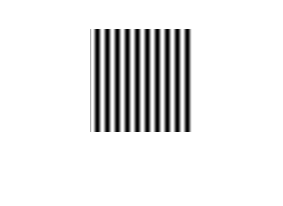

pet=imresize(sine,0.1,'nearest');
figure (2);
imshow(pet,[])

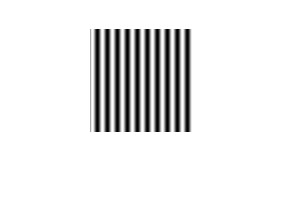

pet=imresize(sine,0.1,'box');
figure (3);
imshow(pet,[])

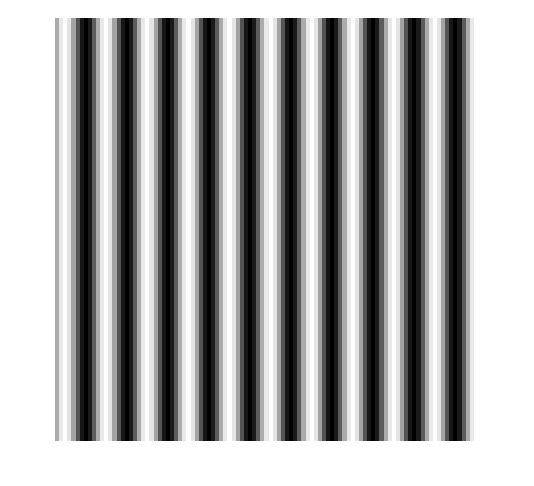

%%muestreo inverso
zoompet=imresize(pet,10,"nearest");
figure(4);
imshow(zoompet,[]);

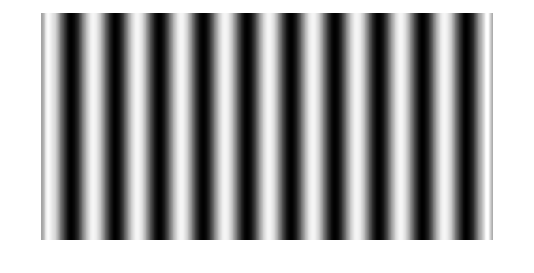

PET=fft2(pet);
ipet=ifft2(fftshift(PET),512,1024);
figure(5);
imshow(abs(ipet),[]);